**MatLab course **- Daeyeol Lee, Alex Kwan, John Murray, ...

**Date&Location**: January-March 2017, Yale University

# [Game of Life](https://en.wikipedia.org/wiki/Conway's_Game_of_Life)

The idea of this lesson is to create the game of life using MatLab. Click on the title to get more information about the theory behind the game. There are a couple of rules in that we need to code in order to determine whether a pixel is alive of dead:

*Rules*: 

- Any live cell with fewer than two live neighbours dies, as if caused by underpopulation.

- Any live cell with two or three live neighbours lives on to the next generation.

- Any live cell with more than three live neighbours dies, as if by overpopulation.

- Any dead cell with exactly three live neighbours becomes a live cell, as if by reproduction.

We will create the script with the following *functions*:

- updates matrix

- update value of each element

## First, create a random matrix

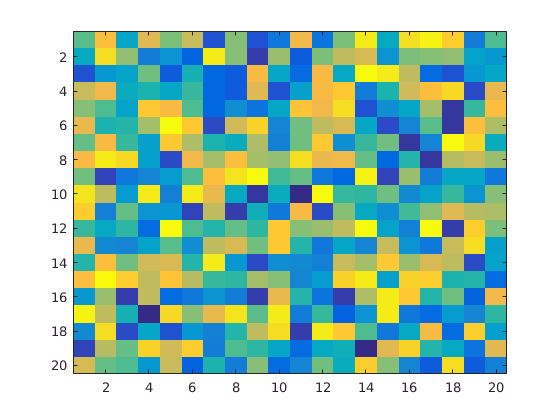

x = rand(20);
imagesc(x)

xlim([0.5 20.5])
ylim([0.5 20.5])

## Now we transform the random matrix into a binary one.

If you like, check out the differences between the x created by rand(20) and x after the restriction by just typing x in the *command window*

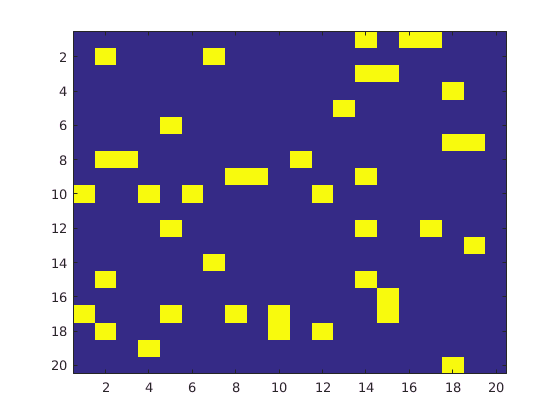

x = x > 0.9;
imagesc(x)

## For loops and while loops 

Click here for more information about the [difference between for and while loops](https://www.mathworks.com/matlabcentral/answers/66814-for-loops-vs-while-loops?). We will create a similar figure, but now using a for loop.

*Do not use i or j when creating for or while loops!*

Some pseudo-code (meaning: it looks like a code, so you know the intentions, but it won't actually run):

`%initialize the universe`

`x = rand(20)>0.9;`

`%run the universe`

`for k =  1:100`

`    imagesc(x);`

`    x_new = update_life_universe(x); %update value x`

`    x = x_new;`

`    pause(0.05);`

`end`

Now, the real deal:

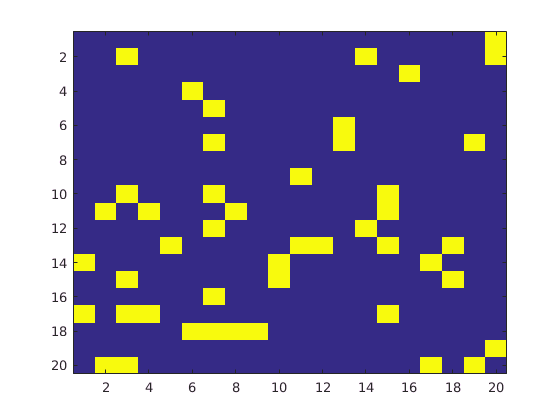

for k = 1:100
    
    x = rand(20)>0.9;
    imagesc(x);
end;

If you use "pause" you will see the frames moving from 1 to 100.

Copy-paste the following lines in your *command window * to see the effect. 

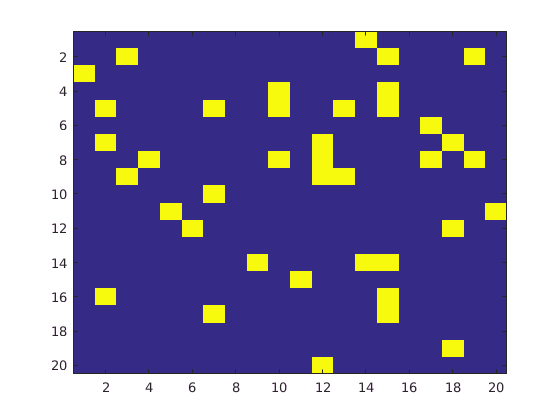

for k = 1:100
    
    x = rand(20)>0.9;
    imagesc(x);
    pause(0.05);
end

## Function that update the universe

We will use a function with a for-loop. The *pseudo-code *looks like:

for nx = 1:maxx,

    for ny = 1:maxy,

        x_new(nx, ny) = update_life_cell(x_old, nx, ny);

    end;

Go to New and choose Function. In the Function editor type:

`function cell_new = update_life_universe (x_old)`

`% update universe in game of life`

`[maxx, maxy] = size(x_old);`

`for nx = 1:maxx`

`    for ny = 1:maxy`

`        cell_new(nx, ny) = update_life_cell(x_old, nx, ny);`

`    end`

`end`

`end`

And save this as "update_life_universe.m"

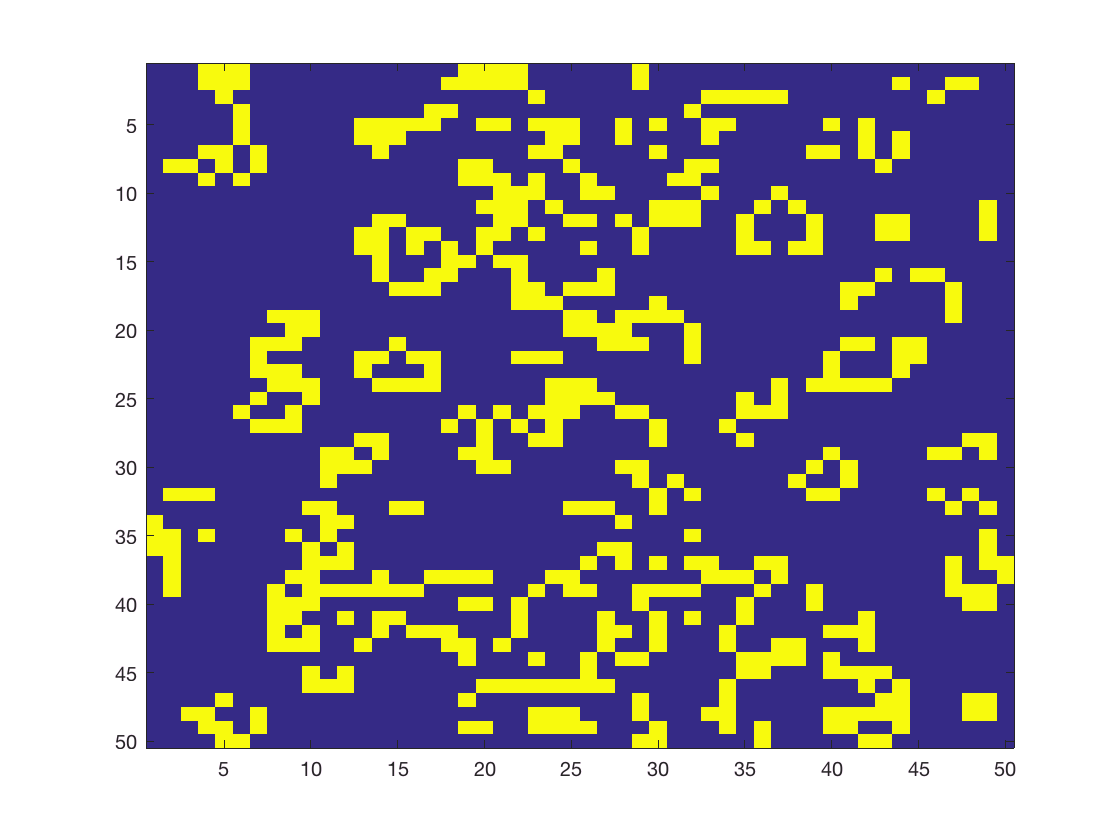

maxuniv = input('Size of universe = ');
plife = input('Probability of life = ');
maxtime = input('Duration of universe = ');

% initialize the universe
x = rand(maxuniv)<plife;

% run the universe
for k =  1:maxtime
    imagesc(x);
    x = update_life_universe(x); 
    pause(0.05);
end

You will see an error message saying that "update_life_cell" is not defined. Therefore, we need to create another function for update_life_cell. 

## Function that update the universe

So, go to New and choose Function to create a new function called "update_life_cell", with the following code. After creating the function re-run the for-loop.

`function cell_new = update_life_cell(xc, nx, ny)`

`% update_life_cell will update cell_new(nx, ny) in game of life`

`%   xc = current universe`

`[maxx, maxy] = size(xc);`

`self_alive = xc(nx, ny);`

`n_alive = 0;`

`for dx = -1:1`

`    for dy = -1:1`

`        if dx==0 && dy==0 `

`            continue;`

`        end`

`        xpos = nx+dx;`

`        ypos = ny+dy;`

`        if xpos<=0 || xpos>maxx `

`            continue;`

`        end`

`        if ypos<=0 || ypos>maxy`

`            continue;`

`        end`

`        if xc(xpos, ypos)>0`

`            n_alive=n_alive+1;`

`        end`

`    end`

`end`

`cell_new = 0;`

`if n_alive==3 `

`    cell_new = 1;`

`elseif n_alive==2 && self_alive>0`

`    cell_new = 1;`

`end`

`end`

Copy-paste the for-loop in the *command window* to see the Game of Life working.